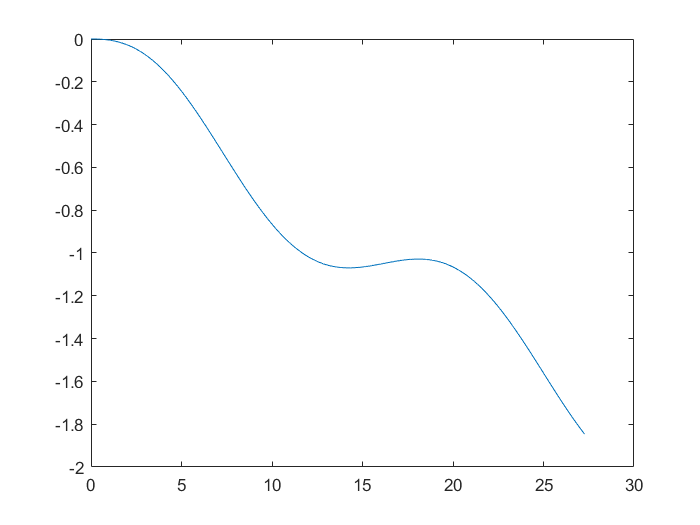

x0 = [0 0 0 5 0 0 0 0];
dt = 0.001;
t = 0:dt:5;
n = max(size(t));
u = [zeros(1,n); 0.4*sin(t); 0.15*cos(2*t)];

x = zeros(n, max(size(x0)));
x(1,:) = x0;
for i = 1:n
    x(i+1,:) = x(i,:) + dt*kin_model(x(i,:),u(:,i))';
end
plot(x(:,1), x(:,2))

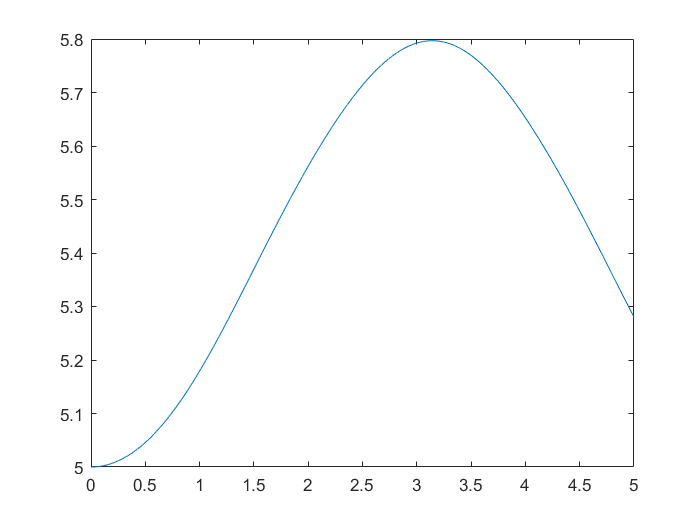

plot(t, x(1:end-1,4))

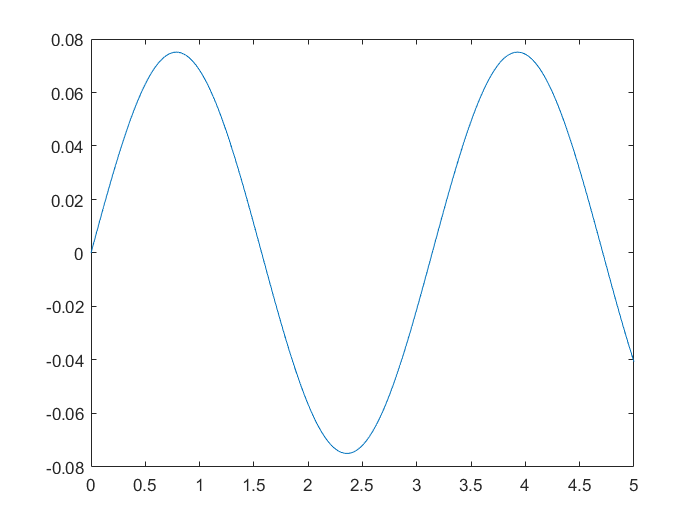

plot(t, x(1:end-1,8))


D = [x(1:end-1,:) u'];
csvwrite("kin_model_data.csv", D)

x0 = [0 0 0 5 0 0 0 0];
dt = 0.001;
t = 0:dt:5;
n = max(size(t));
u = [zeros(1,n); 0.4*sin(t); 0.15*cos(2*t)];

x = zeros(n, max(size(x0)));
x(1,:) = x0;
for i = 1:n
    x(i+1,:) = x(i,:) + dt*dyn_model(x(i,:),u(:,i))';
end
plot(x(:,1), x(:,2))
plot(t, x(1:end-1,4))
plot(t, x(1:end-1,8))

D = [x(1:end-1,:) u'];
csvwrite("dyn_model_data.csv", D)

function [x_dot] = kin_model(x,u)
%u = [v_theta, accel, steer_twist]
%x = [x, y, psi, vx, vy, r, theta, steer_angle] State array definition
%z = [x u]

%% MODEL

  %Create a param object
  p = param;

  %Unpack vehicle state
  psi  = x(3); %heading
  u_x  = x(4); %velocity x
  steer = x(8); %current steering angle
  v_theta = u(1);
  accel = u(2); %commanded accel
  steer_rate = u(3); %commanded steer rate

  %Compute slip angle
  beta = atan( (tan(-steer)*p.lr) / (p.l));

  %Acceleration TODO: orient correctly
  a_x = accel * cos(beta);
  a_y = accel * sin(beta);
  

%% MODEL DYNAMICS

  %Update next state  
  x_dot_1   =  u_x * cos(psi + beta);
  x_dot_2   =  u_x * sin(psi + beta);
  x_dot_3   =  tan(-steer) * (u_x * cos(beta)) / (p.l); % Note: R.Rajamani uses opposite steering coordinates

  %Normal Dynamics 
  x_dot_4 = a_x;
  x_dot_5 = a_y;
  x_dot_6 = (u_x  / p.lr) * sin(beta);

  %Velocity theta
  x_dot_7 = v_theta; 
  %Steering
  x_dot_8 = steer_rate;
  
  
  x_dot = [x_dot_1 x_dot_2 x_dot_3 x_dot_4 x_dot_5 x_dot_6 x_dot_7 x_dot_8]';
end

function [x_dot] = dyn_model(x,u)
%u = [v_theta, accel, steer_target]
%x = [x, y, psi, vx, vy, r, theta, steer_angle]

  %Create param Object
  p = param;

  %Unpack vehicle state
  psi  = x(3); %heading
  u_x  = x(4); %velocity x
  u_y  = x(5); %velocity y
  r    = x(6); %yawrate
  steer = x(8); %current steering angle
  v_theta = u(1); %velocity along path
  D = u(2); %accel command
  delta = u(3); %commanded steer rate

  %Compute slip angles
  alpha_f = atan((u_y + r*p.lf)/u_x) + steer;
  alpha_r = atan((u_y - r*p.lr)/u_x);

  %Estimate Normal
  [FzF, FzR] = normal_force(x,u,p);
  
  %Compute tire forces
  F_yf = tire_force(alpha_f, FzF, p);
  F_yr = tire_force(alpha_r, FzR, p);

  %Torque to force
  F_net = p.mass*D;

  %Torque Vectoring
  F_xf = p.lf / p.l * F_net;
  F_xr = p.lr / p.l * F_net;

  % Acceleration
  a_x = 1/p.mass*(F_xr + F_xf*cos(steer) + F_yf*sin(steer)) + r*u_y;
  
  a_y = 1/p.mass*(F_yr - F_xf*sin(steer) + F_yf*cos(steer)) - r*u_x;
  
  a_yaw = 1/p.Iz*(-p.lf*F_xf*sin(steer) + p.lf*F_yf*cos(steer) - p.lr*F_yr);

  %Standard Dynamics
  x_dot_1 =   u_x*cos(psi) - u_y*sin(psi);
  x_dot_2 =   u_x*sin(psi) + u_y*cos(psi);
  x_dot_3 =   r;
  x_dot_4 =   a_x;
  x_dot_5 =   a_y;
  x_dot_6 =   a_yaw;

  %Velocity theta
  x_dot_7 = v_theta;
  
  %Steering
  x_dot_8 = delta;

  x_dot = [x_dot_1 x_dot_2 x_dot_3 x_dot_4 x_dot_5 x_dot_6 x_dot_7 x_dot_8]';
end

function [FzF, FzR] = normal_force(x,u,p)
    %Moment Balance on car
        %Traction due to aero
        vx = x(4); % Lon Velocity
        F_lift = 0.5*p.rho*p.cla*vx^2;
        %Split forces on front and back axles
        %Takes into account acceleration weight shift
        %FzF = -( p.lr*(p.mass*p.g + F_lift) - p.cg_h*p.mass*u(2) )/ p.l;
        %FzR = -( p.lf*(p.mass*p.g + F_lift) + p.cg_h*p.mass*u(2) )/ p.l;
        FzF = -( p.lr*(p.mass*p.g + F_lift))/ p.l;
        FzR = -( p.lf*(p.mass*p.g + F_lift) )/ p.l;
        
     %Outputs forces (positive downforce)

end

function F = tire_force(alpha,Fz,p)

F = -alpha .* p.cornering_stiff .* (Fz/p.sample_fz);

end